# Computer Assignment #5

## Ali Hamzehpour 810100129

### Part 1

### 1-0

    First, we show the fourier transform of the given function below where $f_s =20$ and $T=1\;$:

#### 
$$x_1 \left(t\right)=\exp \left(1j*2\pi *5*t\right)+\exp \left(1j*2\pi *8*t\right)$$


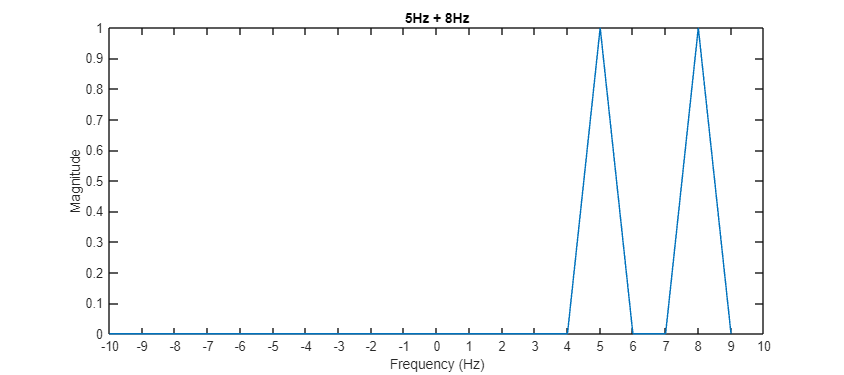

T = 1;
fs = 20;
t = 0 : 1/fs : T - 1 / fs;
f = -10 : 1 : 9;

x1 = exp(1i * 2 * pi * 5 * t) + exp(1i * 2 * pi * 8 * t);
y1 = fftshift(fft(x1));
y1 = y1 / max(abs(y1));

figure('Position', [0, 0, 900, 400]);
plot(f, abs(y1));
xlim([-10, 10]);
title("5Hz + 8Hz");
xticks(-10 : 1 : 10);
xlabel("Frequency (Hz)");
ylabel("Magnitude");

As you can see we have two peaks in the fourier transform which is the freqeuncy of those two single-tone signals.

Now we do the same thing with this function which the frequencies are 5 and 5.1:

#### 
$$x_2 \left(t\right)=\exp \left(1j*2\pi *5*t\right)+\exp \left(1j*2\pi *5\ldotp 1*t\right)$$


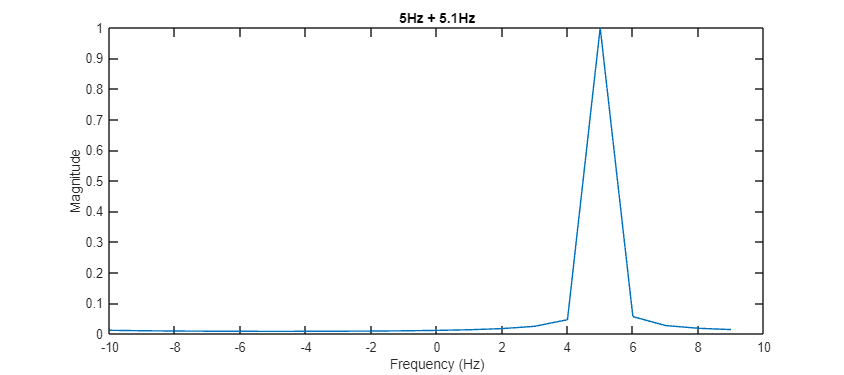

x2 = exp(1i * 2 * pi * 5 * t) + exp(1i * 2 * pi * 5.1 * t);
y2 = fftshift(fft(x2));
y2 = y2 / max(abs(y2));

plot(f, abs(y2));
xlim([-10, 10]);
title("5Hz + 5.1Hz");
xlabel("Frequency (Hz)");
ylabel("Magnitude");

As you can see we only have one peak in f = 5, Because the resolution is $\delta =\frac{1}{T}=1$ and we can't distinguish f = 5 and f = 5.1 with this resolution.

### 1-1

  First we plot $x_1 \left(t\right)=\cos \left(10\pi *t\right)$ from $t_{\textrm{start}\;} =1\;$ to $t_{\textrm{end}} =1$where $f_s =50$ then we plot the fourier transform of the function.

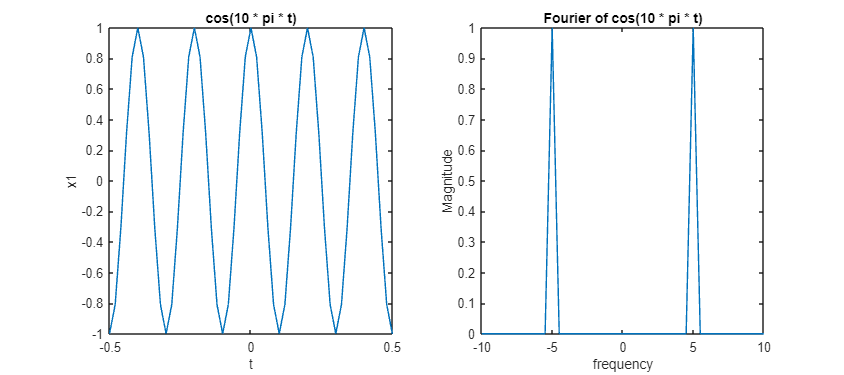

t_start = -1;
t_end = 1;
fs = 50;
t = t_start : 1/fs : t_end - 1 / fs;
N = length(t);
f = -fs/2 : fs/N : fs/2 - fs/N;

x1 = cos(10 * pi * t);

figure('Position', [0, 0, 900, 400]);
subplot(1, 2, 1);
plot(t, x1);
title("cos(10 * pi * t)");
xlim([-0.5, 0.5]);
xlabel("t");
ylabel("x1");


y1 = fftshift(fft(x1));
y1 = y1 / max(abs(y1));
subplot(1, 2, 2);
plot(f, abs(y1));
xlim([-10, 10]);
title("Fourier of cos(10 * pi * t)");
xlabel("frequency");
ylabel("Magnitude");

The fourier result makes sense because the fourier transform of the function is

#### 
$$F\left\lbrace \cos \left(10\pi t\right)\right\rbrace =\pi \left(\delta \left(\omega +10\pi \right)+\delta \left(\omega -10\pi \right)\right)$$


Because in this project we define $f=2\frac{\pi }{T}=2\pi \omega$, The peak should happen at f = 5 and f= -5.

### 1-2

In this part we do the same thing on $x_2 \left(t\right)=\cos \left(30\pi t+\frac{\pi }{4}\right)$ where $t_{\textrm{start}} =0$, $t_{\textrm{end}} =1$ and $f_s =100$:

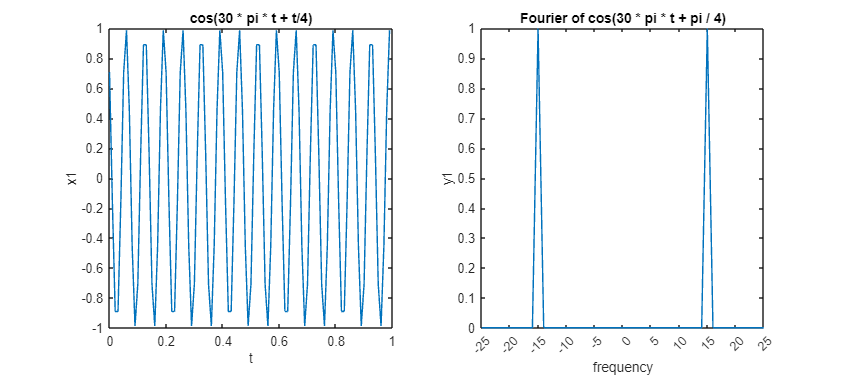

t_start = 0;
t_end = 1;
fs = 100;
t = t_start : 1/fs : t_end - 1 / fs;
N = length(t);
f = -fs/2 : fs/N : fs/2 - fs/N;

x1 = cos(30 * pi * t + pi / 4);

figure('Position', [0, 0, 900, 400]);
subplot(1, 2, 1);
plot(t, x1);
title("cos(30 * pi * t + t/4)");
xlabel("t");
ylabel("x1");


y1 = fftshift(fft(x1));
y1 = y1 / max(abs(y1));
subplot(1, 2, 2);
plot(f, abs(y1));
title("Fourier of cos(30 * pi * t + pi / 4)");
xlim([-25 25])
xticks(-25 : 5 : 25)
xlabel("frequency");
ylabel("y1");

Now we calculate the fourier transform by hand:

We know the fourier transform of $\cos$ function:

####     
$$F\left\lbrace \cos \left(30\pi t\right)\right\rbrace =\pi \left(\delta \left(\omega +30\pi \right)+\delta \left(\omega -30\pi \right)\right)$$


Now we have a shift which doesn't change the magnitude and only chnages the phase:

#### 
$$F\left\lbrace \cos \left(30\pi t+\frac{\pi }{4}\right)\right\rbrace =\pi \;*\left(\exp \left(j*\frac{\pi }{4}\right)*\delta \left(\omega -30\pi \right)+\exp \left(-j*\frac{\pi }{4}\right)*\delta \left(\omega +30\pi \right)\right)$$


Again because $f=2\frac{\pi }{T}=2\pi \omega$, the peak happens where f = 15 and f = -15. Also the angle in those points will be $\frac{\pi }{4}$ and $-\frac{\pi }{4}$ so $\textrm{phase}\;/\;\pi =\frac{1}{4},-\frac{1}{4}$.

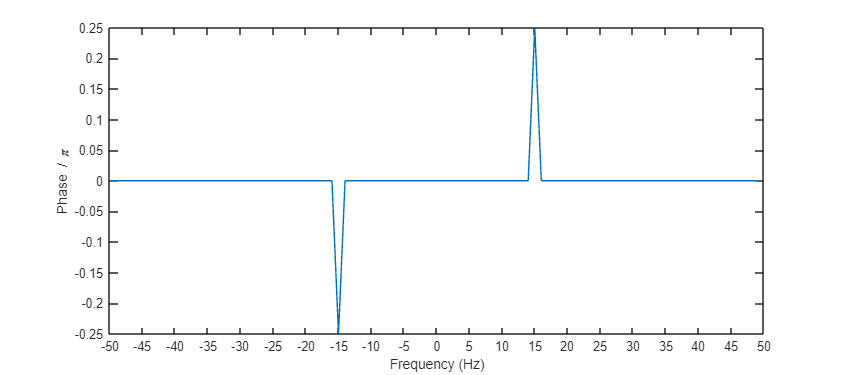

figure('Position', [0, 0, 900, 400]);
tol = 1e-6; 
y1(abs(y1) < tol) = 0; 
 
theta = angle(y1); 
 
plot(f,theta/pi) 
xticks(-50 : 5 : 50)
xlabel('Frequency (Hz)')
ylabel('Phase / \pi')

### Part 2

Like last project we want to encode a message in a signal but instead of amplitude, we use different frequencies to indicate different bit codes.

### 2-1

First, We make the mapset. we map each character to a 5-bit string:

map_set = cell(2, 32);

letters = ['a':'z'];
for i = 1:numel(letters)
    binary_string = dec2bin(i-1, 5);
    map_set{1, i} = letters(i);
    map_set{2, i} = binary_string;
end

special_chars = [' ', '!', '.', ',', '"', ';'];
for i = 1:numel(special_chars)
    binary_string = dec2bin(i+25, 5);
    map_set{1, i+26} = special_chars(i);
    map_set{2, i+26} = binary_string;
end

### 2-2

We implemet a function called *coding_freq *which gets the map set, a message and the rate of the encoding. For each code we set its frequeny like below:

#### 
$$\textrm{frequency}=\left\lfloor \frac{49}{2^{\textrm{rate}} }\right\rfloor +\frac{49}{2^{\textrm{rate}+1} }$$


With this formula, the distance between each frequency will be identical and also the distance is to some extent maximum.

function x = coding_freq(map_set, msg, rate)
    msg_code = '';
    for i = 1 : length(msg)
        char_code = map_set{2, strcmp(map_set(1, :), msg(i))};
        msg_code = [msg_code, char_code];
    end 
    msg_code = [msg_code];

    fs = 100;
    
    t = 0 : 1 / fs : (length(msg_code) / rate);
    x = zeros(1, length(t));
    sec = 0;
    for i = 1 : rate : length(msg_code)
        if i + rate - 1 > length(msg_code)
            break;
        end
        code = msg_code(i : i + rate - 1);
        code = bin2dec(code);
        frequency = floor(49 / (2 ^ rate)) * code + (49/(2 ^ (rate + 1)));

        start_index = sec * fs + 1;
        end_index = start_index + fs;        
        x(start_index : end_index) = sin(2 * pi * frequency * t(start_index : end_index));
        sec = sec + 1;
    end
end

### 2-3

In this section, We test our function with message = 'signal' and bit rate = 1 and 5:

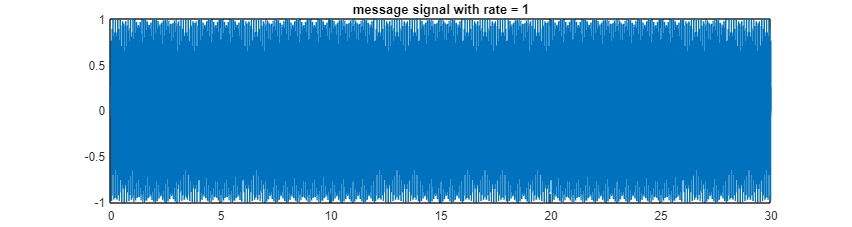

WORD = 'signal';

fs = 100;

figure('Position', [0, 0, 3000, 800]);
x1 = coding_freq(map_set, WORD, 1);
t1 = 0:1/fs:(length(x1)-1)/fs;
plot(t1, x1);
title('message signal with rate = 1');

This is the signal with bit-rate = 1 with more details:

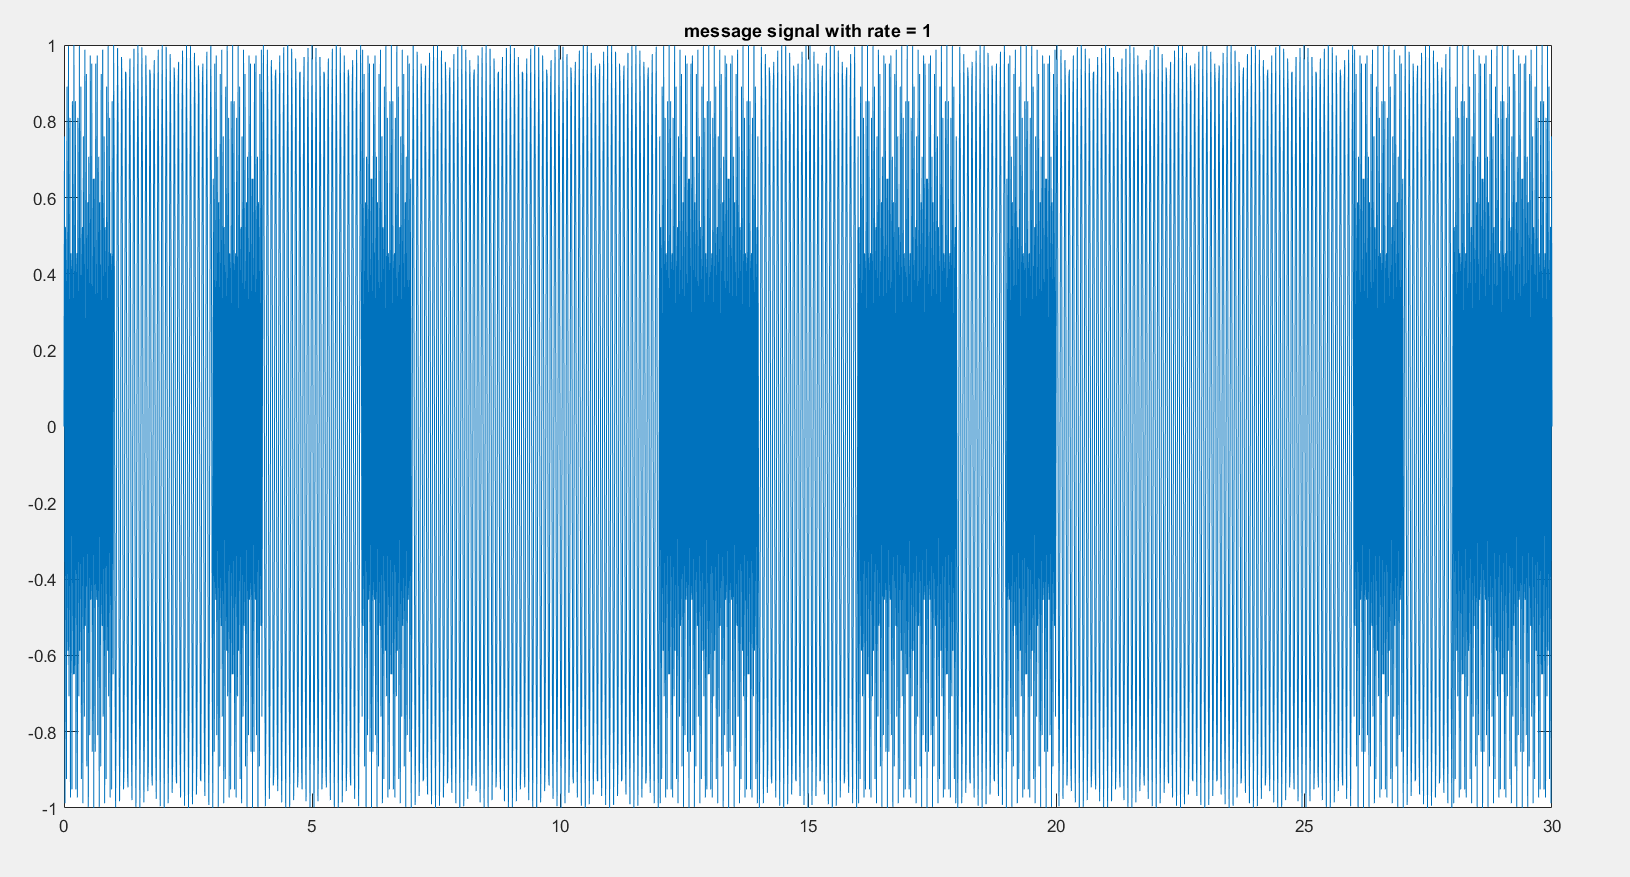

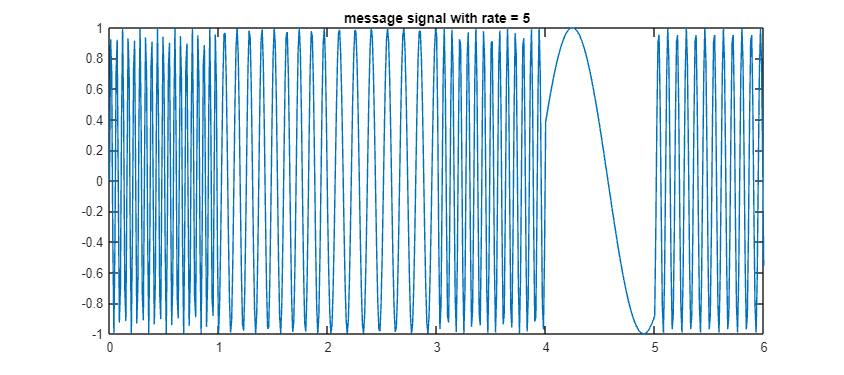

figure('Position', [0, 0, 900, 400]);
x2 = coding_freq(map_set, WORD, 5);
t2 = 0:1/fs:(length(x2)-1)/fs;
plot(t2, x2);
title('message signal with rate = 5');

### 2-4

In this section, we implement a function called *decoding_freq *which gets a signal, map-set and a bit-rate and decode the hidden message in the signal. We use fourier transform to find the frequency of each part of the signal then we find the binary code for that part using the frequency.

function msg = decoding_freq(map_set, coded_msg, rate);
    fs = 100;
    sec = 0;
    binary_msg = '';
    msg = '';
    for i = 1 : fs : length(coded_msg) - 1
         start_index = sec * fs + 1;
         end_index = start_index + fs;  
         slice = coded_msg(start_index : end_index);
         f = -fs/2 : fs/length(slice) : fs/2 - fs/length(coded_msg);
         fourier = fftshift(fft(slice));
         [mx_fourier, mx_freq] = max(abs(fourier));
         mx_freq = abs(mx_freq - floor(fs / 2) - 1);
         for code = 0 : 2 ^ rate - 1
            cur_frequency = floor(49 / (2 ^ rate)) * code  + (49/(2 ^ (rate + 1)));
            
            if abs(mx_freq - cur_frequency) <= (49/(2 ^ (rate + 1)))
                bin_code = dec2bin(code);
                extended = strcat(repmat('0', 1, rate - numel(bin_code)), bin_code);
                binary_msg = [binary_msg, extended];
                break;
            end
         end 
         sec = sec + 1;
    end 
    for i = 1 : 5 : length(binary_msg) - 4
         msg = [msg, map_set{1, strcmp(map_set(2, :), binary_msg(i : i + 4))}];
    end
 
 end




Now we decode the signals that we encoded in part 2-3:

msg1 = decoding_freq(map_set, x1, 1);
msg2 = decoding_freq(map_set, x2, 5);
fprintf('message with rate = 1: %s\n', msg1);

message with rate = 1: signal


fprintf('message with rate = 5: %s\n', msg2);

message with rate = 5: signal


### 2-5

Next, we add a gaussian noise with varaince = 0.0001 to see how our decoding can perform when we have noise:

normal = randn(size(x1));
std = 0.01; 
x1_noise = x1 + std * normal;
x2_noise = x2 + std * normal(1 : length(x2));
msg1 = decoding_freq(map_set, x1_noise, 1);
msg2 = decoding_freq(map_set, x2_noise, 5);
fprintf('message with rate = 1 and noise 0.0001: %s\n', msg1);

message with rate = 1 and noise 0.0001: signal


fprintf('message with rate = 5 and noise 0.0001: %s\n', msg2);

message with rate = 5 and noise 0.0001: signal


As you can see, both bit-rates performed well and we got the correct result.

#### 2-6 & 2-7

Now we increase the variance to see how these two bit-rates perform against stronger noises:

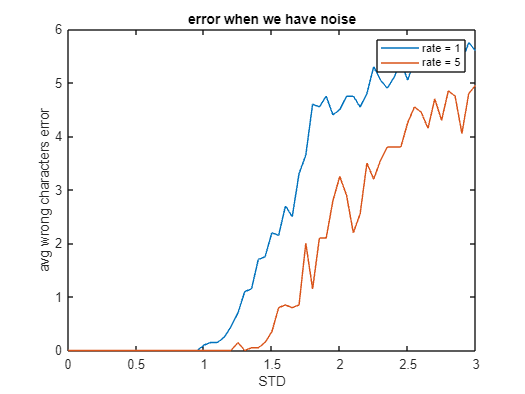

ITERATION_NUM = 20;
max_noise = zeros(1, 5);
stds = 0 : 0.05 : 3;
error_1_bit = zeros(size(stds));
error_5_bit = zeros(size(stds));
for i = 1 : length(stds)
    std = stds(i);
    for j = 1 : ITERATION_NUM
        normal = randn(size(x1));
        x1_noise = x1 + std * normal;
        x2_noise = x2 + std * normal(1 : length(x2));
        msg1 = decoding_freq(map_set, x1_noise, 1);
        msg2 = decoding_freq(map_set, x2_noise, 5);
        for k = 1 : length(WORD)
            if length(msg1) < k
                error_1_bit(i) = error_1_bit(i) + 1;
            elseif msg1(k) ~= WORD(k)
                error_1_bit(i) = error_1_bit(i) + 1;
            end
            if length(msg2) < k
                error_5_bit(i) = error_5_bit(i) + 1;
            elseif msg2(k) ~= WORD(k)
                error_5_bit(i) = error_5_bit(i) + 1;
            end
        end
        if error_1_bit(i) == 0
            max_noise(1) = std;
        end
        if error_5_bit(i) == 0
            max_noise(2) = std;
        end

    end
    error_1_bit(i) = error_1_bit(i) / ITERATION_NUM;
    error_5_bit(i) = error_5_bit(i) / ITERATION_NUM;
end
figure;
plot(stds, error_1_bit);
hold on;
plot(stds, error_5_bit);
legend('rate = 1', 'rate = 5');
title("error when we have noise")
xlabel("STD")
ylabel("avg wrong characters error")

fprintf('max noise for rate = 1: %f\n', max_noise(1));

max noise for rate = 1: 1.500000


fprintf('max noise for rate = 5: %f\n', max_noise(2));

max noise for rate = 5: 2.300000


As you can see bit-rate 5 works better and has less error and also maximum std which the signal is still tolerant is more. This doesn't match our theory because in bit-rate = 1, we have more distance between the frequencies so we expected it to be more tolerant to noise than bit-rate = 5

### 2-8

***    How can we make our signal more tolerant to noise without changing the bit-rate?***

    If we increase the distance between the freqeuncies for each binary string, our signal will be more tolerant the noise needs to change the maximum frequency of the signal more than before. We increase this distance by increasing the band-width.

### 2-9

***    If we increase sampling rate (fs) but we don't change the band-width, will our signal be more tolerant to noise, too?***

    No because, what matters is band-width and if the band-width don't change, it means that the maximum distance between freqeuncies can't change so our signal won't be more tolerant to noise. If we increase fs and use it to increase our band-width then we can generate a better signal that is more tolerant to noise.